## Calibration 

%Removal of gyroscope bias

%Method add steady state calibration data to start of data

%Read in calibration data to table
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["DateTimeUTC","Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];
calData = readtable("IMU_5_Calibration.TXT", opts);

%Remove Count from wave data
waveData = removevars(WaveSampleTable, "timeSeriesCount");

%Add steady state data to start of measurement:
calibrationDataset = [calData; waveData];

## Preprocess Vertical Acceleration: Roll, Pitch Sensor Fusion 

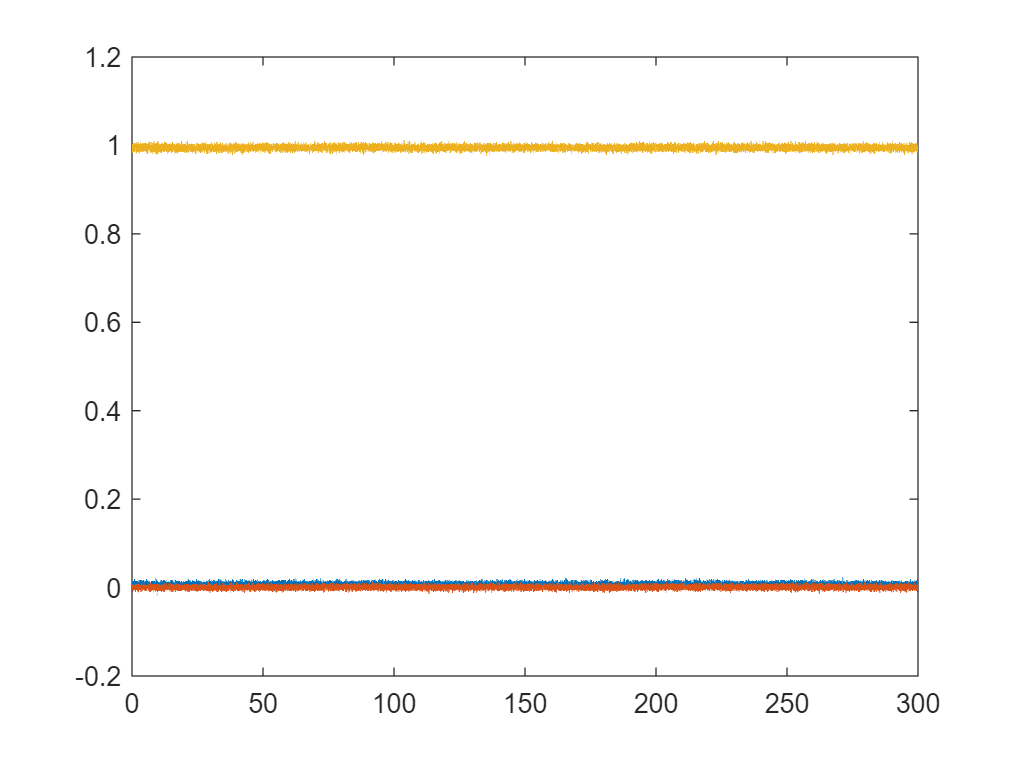

%Parameters 
gyroNoise = convangvel(0.49, 'deg/s', 'rad/s');
accNoise = 10*1/1000*9.81;
Fs = 100;
time = (0:height(calData)-1)'/Fs;

%Readings
calAcc = [calData.Surge/8192, calData.Sway/8192, calData.Heave/8192];
calGyro = [calData.Roll/65.5*(1/(2*pi)), calData.Pitch/65.5*(1/(2*pi)), calData.Yaw/65.5*(1/(2*pi))];
accReading = [waveData.Surge/8192, waveData.Sway/8192, waveData.Heave/8192];
gyroReading = [waveData.Roll/65.5*(1/(2*pi)), waveData.Pitch/65.5*(1/(2*pi)), waveData.Yaw/65.5*(1/(2*pi))];

plot(time, calAcc);

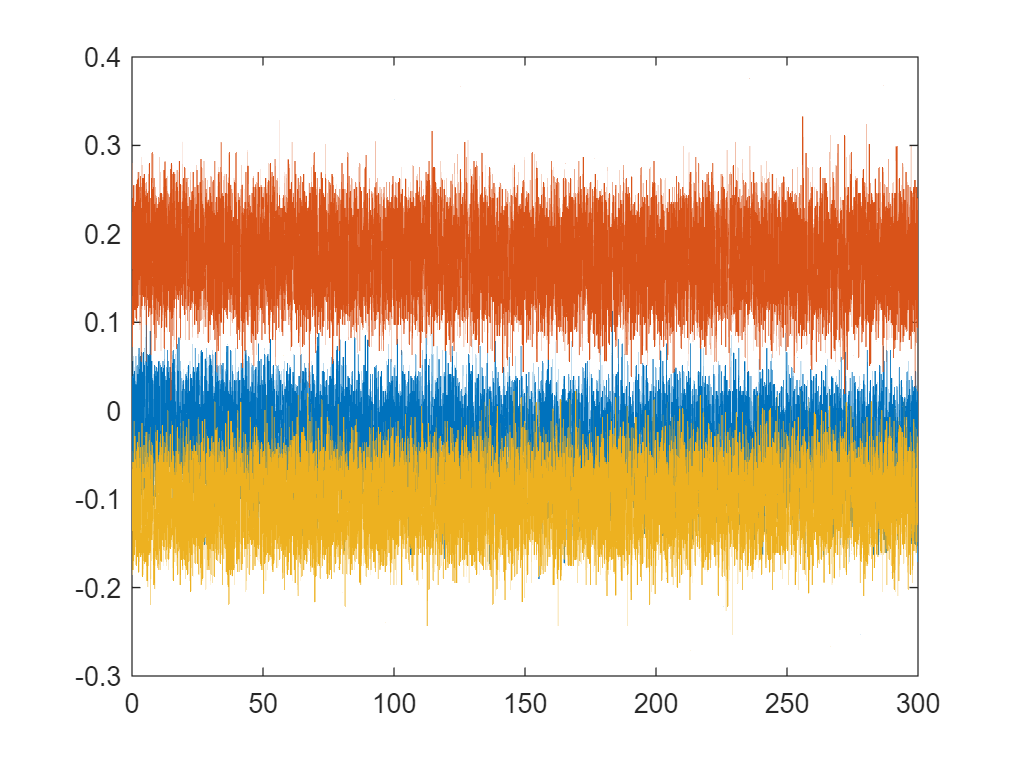

plot(time, calGyro);

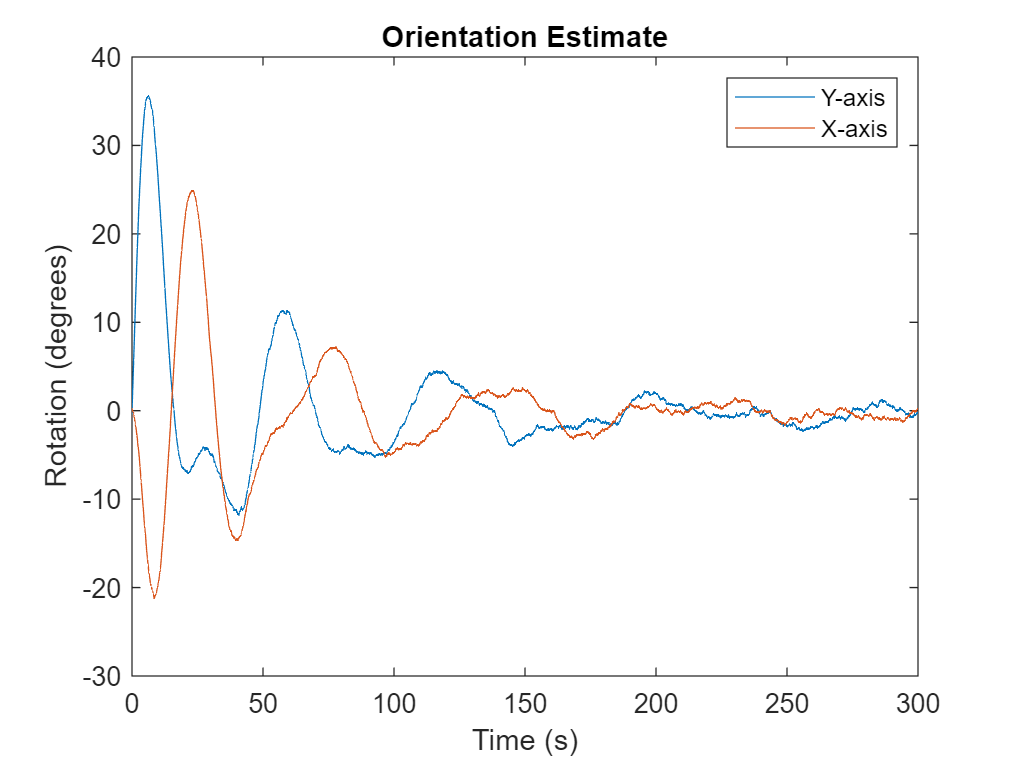


Fuse = imufilter('SampleRate', Fs, 'ReferenceFrame', 'NED'); %, "AccelerometerNoise", accNoise, "GyroscopeNoise", gyroNoise);

cal = Fuse(calAcc, calGyro);

eulerAngles = eulerd(cal,'ZYX','frame'); 

plot(time, eulerAngles(:, 2), time, eulerAngles(:, 3));
title('Orientation Estimate');
legend('Y-axis', 'X-axis');
xlabel('Time (s)');
ylabel('Rotation (degrees)');

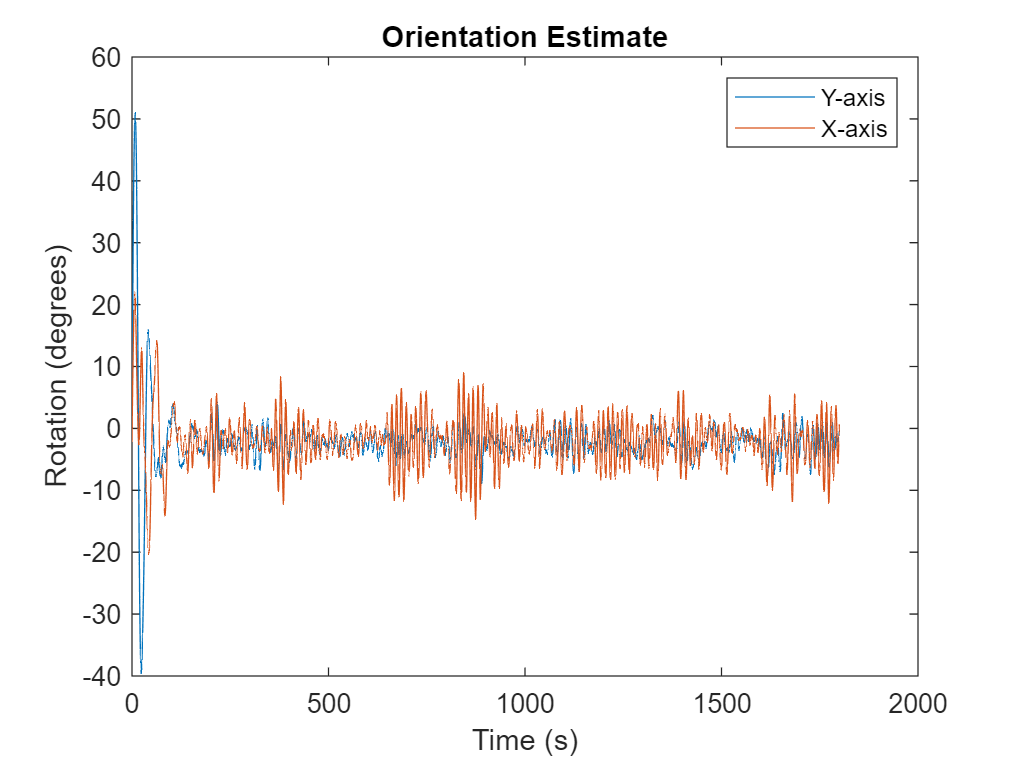


%Create clone of system object to preserve states
FuseClone = clone(Fuse);
time = (0:1:size(calAcc,1)-1)/Fs;

reset(FuseClone);
q = FuseClone(accReading, gyroReading);

time = (0:1:size(accReading,1)-1)/Fs;

eulerAngles = eulerd(q,'ZYX','frame'); 

plot(time, eulerAngles(:, 2), time, eulerAngles(:, 3));
title('Orientation Estimate')
legend('Y-axis', 'X-axis');
xlabel('Time (s)')
ylabel('Rotation (degrees)')

## Truncate Series to remove initial transient response 

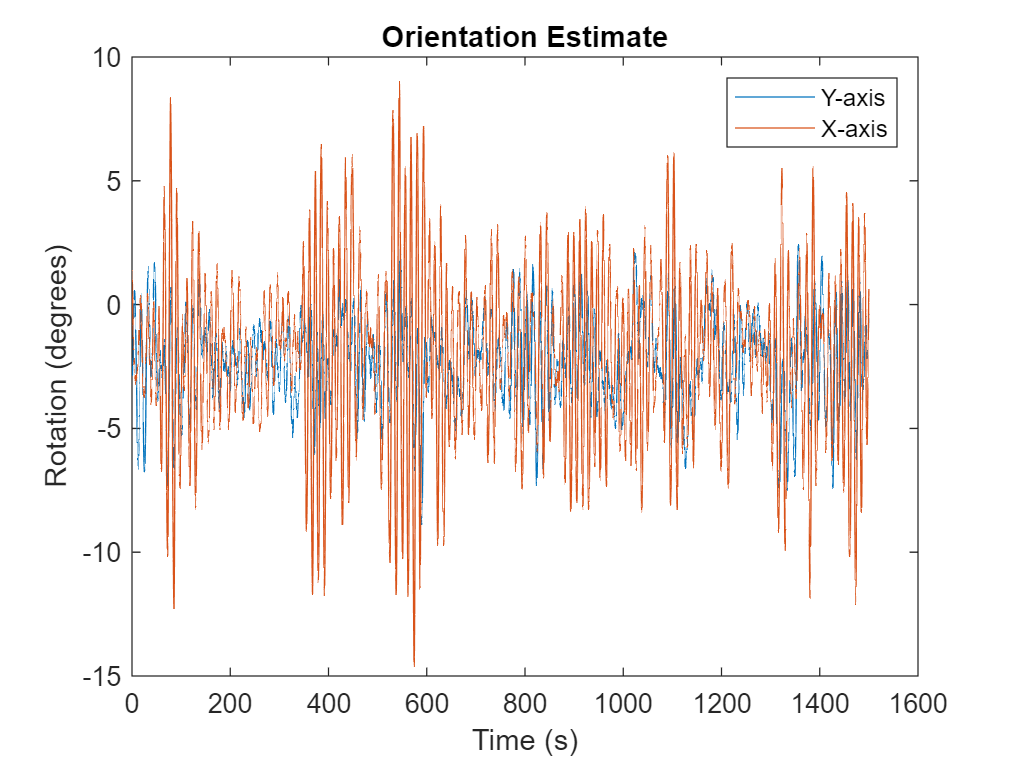

Fs = 100;

%Remove first 5 minutes 
accFilter = accReading(Fs*300:end, :);
gyroFilter = eulerAngles(Fs*300:end, :); 

time = (0:1:size(accFilter,1)-1)/Fs;
time = time';

plot(time, gyroFilter(:, 2:end));
title('Orientation Estimate')
legend('Y-axis', 'X-axis');
xlabel('Time (s)')
ylabel('Rotation (degrees)')

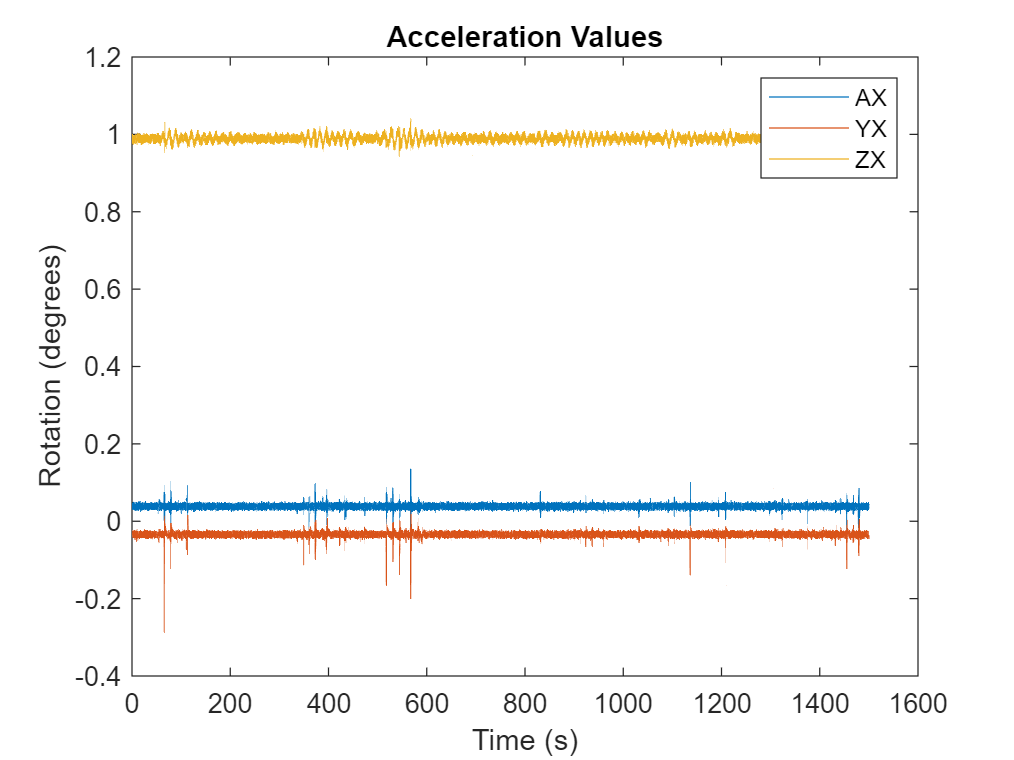


plot(time, accFilter);
title('Acceleration Values');
legend("AX", "YX", "ZX");
xlabel('Time (s)');
ylabel('Rotation (degrees)');

## Filter Acceleration Values 

- Remove bias (detrend)

- Lowpass to remove noise

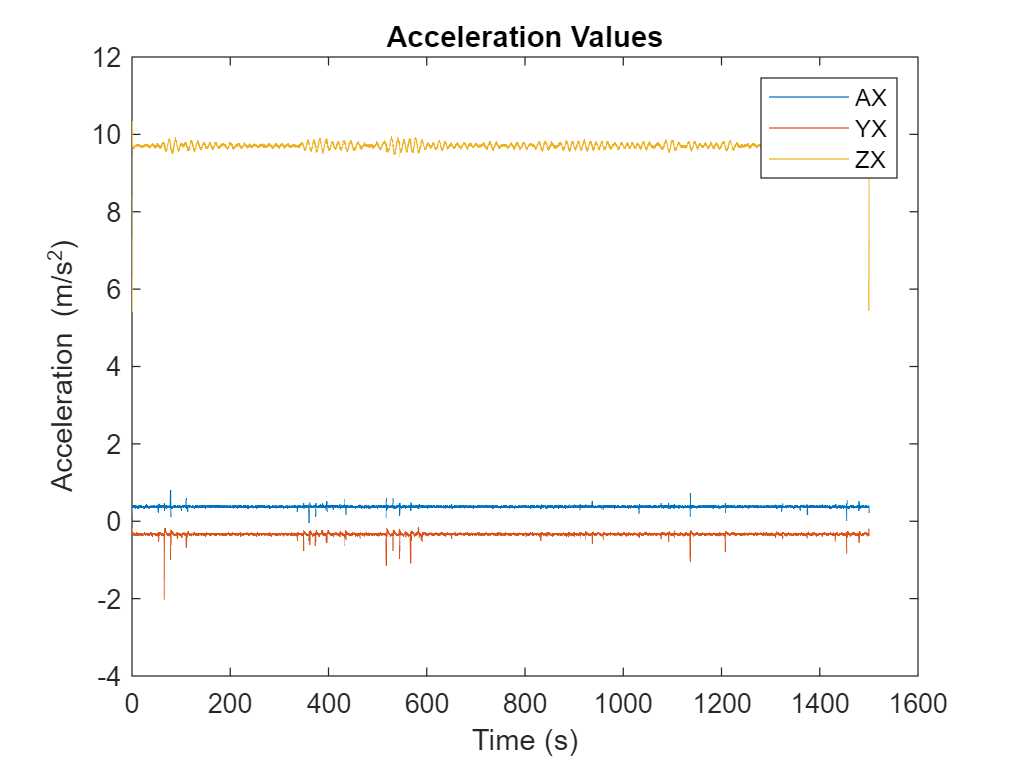

%accFilter = detrend(accFilter); 
accFilter = lowpass(accFilter, 2, 100);
accFilter = accFilter*9.812;

plot(time, accFilter);
title('Acceleration Values');
legend("AX", "YX", "ZX");
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

## Apply stand correction for acceleration values 

%TODO: Current correct assumes small angle - this becomes innacurate 
%Implement full Euler solution with rotation matrix

Surge = accFilter(:, 1);
Sway = accFilter(:, 2);
Heave = accFilter(:, 3);
Pitch = gyroFilter(:, 2);
Roll = gyroFilter(:, 3);

r = 0.90 %Approximate IMU elevation in m 

r = 0.9000

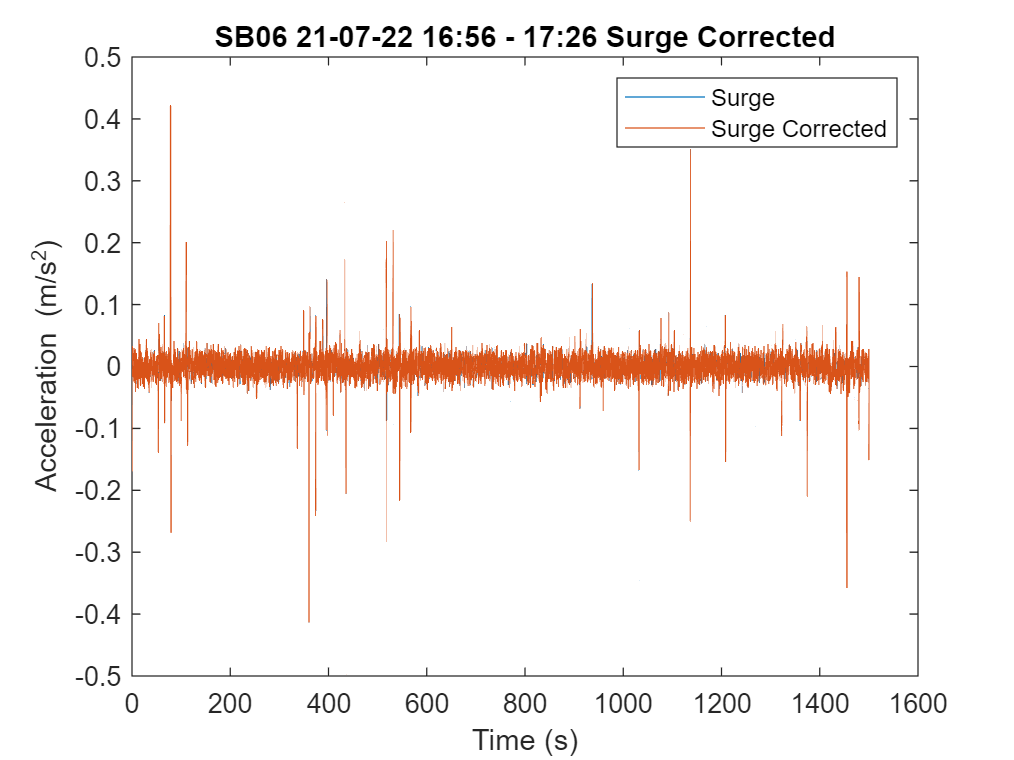


R = zeros(length(Pitch), 3);

%Calculate angular velocity and acceleration 
omega = zeros(length(Pitch), 3);
alpha = zeros(length(Pitch), 3);

omega(1:end -1, 2) = diff(deg2rad(Pitch));
alpha(1:end -1, 2) = diff(omega(:, 2));
omega(1:end -1, 1) = diff(deg2rad(Roll));
alpha(1:end -1, 1) = diff(omega(:, 1));
    
%Matrix with relative height
R(:, 3) = R(:, 3) + r;

%relative acceleration of buoy to pancake
acc_buoy_pancake = cross(omega, cross(omega, R)) + cross(alpha, R);

%Surge Correction

    %Surge correct: Subtract relative motion
    SurgePancake = Surge - acc_buoy_pancake(:, 1); 

    %Surge Correction 
    plot(time, detrend(Surge), time, detrend(SurgePancake));
    legend("Surge", "Surge Corrected");
    title('SB06 21-07-22 16:56 - 17:26 Surge Corrected');
    xlabel('Time (s)');
    ylabel('Acceleration (m/s^2)');

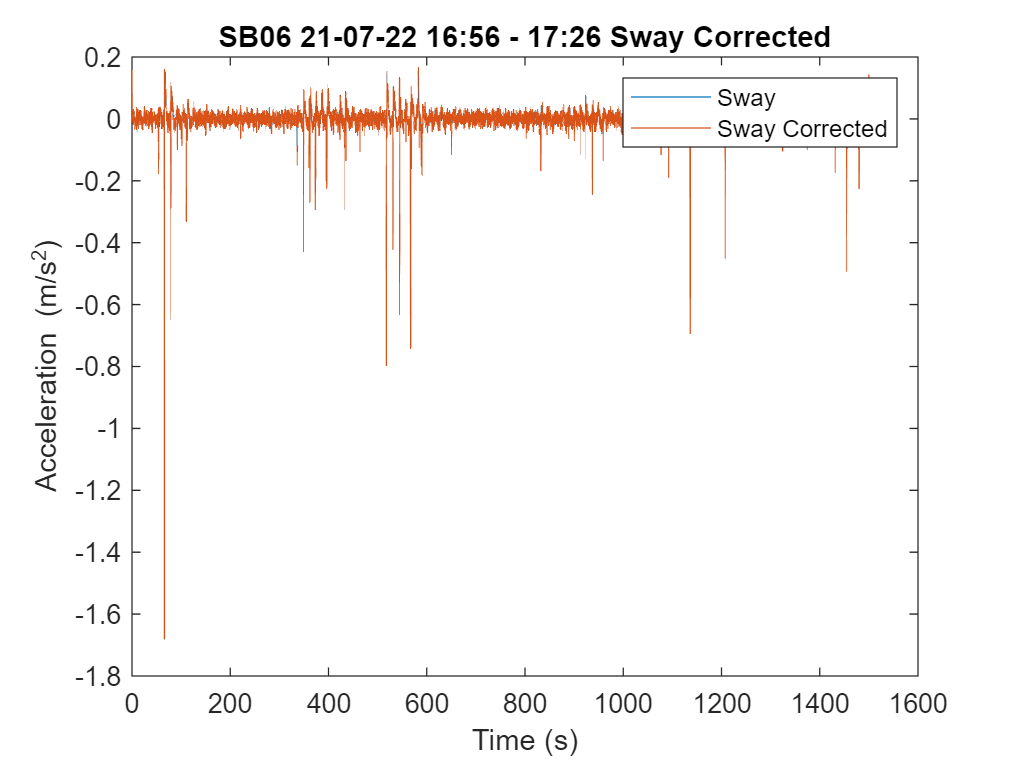



%Sway Correction

    %Sway correct using 
    SwayPancake = Sway - acc_buoy_pancake(:, 2); 

    %Sway Correction 
    plot(time, detrend(Sway), time, detrend(SwayPancake));
    title('SB06 21-07-22 16:56 - 17:26 Sway Corrected');
    legend("Sway", "Sway Corrected");
    xlabel('Time (s)');
    ylabel('Acceleration (m/s^2)');

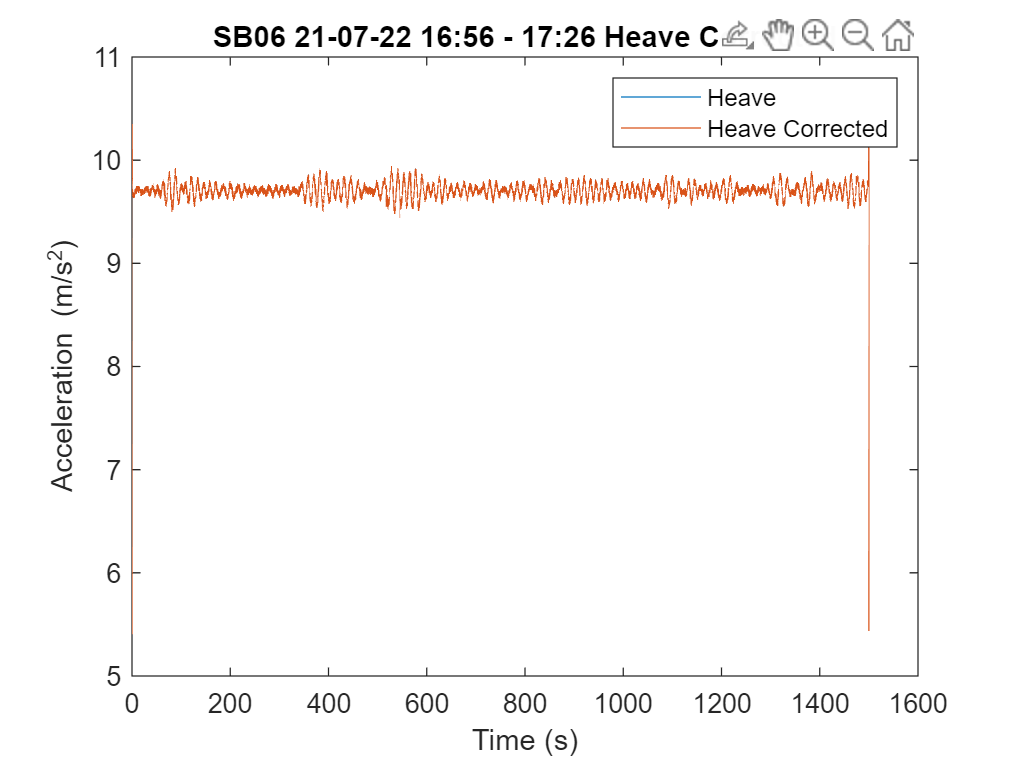


%Heave Correction
    
    %Heave correct using 
    HeavePancake = Heave - acc_buoy_pancake(:, 3); 

    %Heave Correction 
    plot(time, Heave, time, HeavePancake);
    title('SB06 21-07-22 16:56 - 17:26 Heave Corrected');
    legend("Heave", "Heave Corrected");
    xlabel('Time (s)');
    ylabel('Acceleration (m/s^2)');

## Combine Values (correct to vertical) 

%Parameters
Surge = accFilter(:, 1); 
Sway = accFilter(:, 2); 
Heave = accFilter(:, 3); 

Roll = gyroFilter(:, 3); 
Pitch = gyroFilter(:, 2); 
Yaw = gyroFilter(:, 1); 

g = 9.812;

%Correction 1: Just Heave 
vertAcc1 = Heave - g;


time = (0:1:size(accFilter,1)-1)/Fs;
time = time';

plot(time, vertAcc1);
title('Vertical Acceleration: Heave Only');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


%Correction 2: Roll and Tilt 
g = 9.812;
vertAcc2 = Heave - ( g.*cosd(Roll).*cosd(Pitch) ); 

plot(time, vertAcc2);
title('Vertical Acceleration: Roll and Tilt Correction');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

%Correction 3: Roll Tilt 
Heave = detrend(HeavePancake);
Surge = detrend(SurgePancake);
Sway = detrend(SwayPancake);
vertAcc3 = (sind(Pitch).*SurgePancake + sind(Roll).*cosd(Pitch).*SwayPancake + cosd(Roll).*cosd(Pitch).*Heave) -g ;

plot(time, vertAcc3);
title('Vertical Acceleration: Roll Tilt and X+Y acceleration');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


%Plot 3 corrections together to determine difference
plot(time, vertAcc1, time, vertAcc2, time, vertAcc3);
title('Vertical Acceleration: Comparison of methods');
legend('Heave - g', 'Heave - ( g.*cosd(Roll).*cosd(Pitch) ', '(sind(Pitch).*SurgePancake + sind(Roll).*cosd(Pitch).*SwayPancake + cosd(Roll).*cosd(Pitch).*Heave) -g');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');



## Integration to Displacement

%Tranform to the frequency domain 
y = fft(vertAcc3);
y = fftshift(y);

%Double integration in the frequency domain

f1 = 0.02; %Lower corner frequency for half cosine taper
f2 = 0.03; %Upper frequency for half cosine taper
fc = 1; 

Nfft = length(y);

%frequency array 
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft

f =   -50.0000
  -49.9993
  -49.9987
  -49.9980
  -49.9973
  -49.9967
  -49.9960
  -49.9953
  -49.9947
  -49.9940


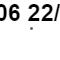

N = size(f, 1); 

%Fourier filter 
% Rf = response frequency weights
Rf = zeros(N, 1);

for i = 1:length(f)
    if f(i) < f1 
       Rf(i, 1) = 0;
    end
        if f(i) > f1 & f(i) < f2
            Rf(i, 1) = (1/2)*(1-cos(pi*(f(i)-f1)/(f2-f1))*(-1/(2*pi*f(i)^2)));
        end
            if f(i) > f2 & f(i) < fc
                Rf(i, 1) = -1/(2*pi*f(i)^2); 
            end
end

%Acceleration .* Rf
elevFFT = y.*Rf; 

%Elevation 
elev = ifft(fftshift(elevFFT)); 

%Remove 30s from each side 
sec_30 = Fs*30; 
min_5 = Fs*5*60;
elev = real(elev);
elev = elev(sec_30:(end-sec_30));

%Plot elevation output 
timeSeries = WaveTimeTable.Time(sec_30 + min_5 :(end-sec_30));
plot(timeSeries, elev(1:end -1));
title("Wave Elevation SB06 22/07/2022 14:50-15:20")
xlabel('Time (s)')
ylabel('Elevation (m)')

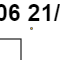


%Plot all time series: elevation output method 
timeSeries = WaveTimeTable.Time(sec_30 + min_5 :(end-sec_30));
plot(timeSeries, elev1(1:end -1), timeSeries, elev2(1:end -1), timeSeries, elev3(1:end -1));
title("Wave Elevation SB06 21/07/2022 21:33-22:03")
legend("Heave only", "Roll Pitch Heave", "Roll Pitch and 3DOF Acc");
xlabel('Time (s)')
ylabel('Elevation (m)')

## PSD Estimate (Welch's Method)


%Welch Method
Window = 5 * 60 * 100; 
segmentLength = 60*5*100;
nooverlap = segmentLength/2; 

[pxx, f, pxxc] = pwelch(elev, segmentLength, [], segmentLength, 100, "onesided", 'ConfidenceLevel', 0.90); 

%Plot Elevation PSD (Welch)
plot(f, pxx, f, pxxc);
title("Wave Spectrum SB06 21/07/22 17:37 - 18:07")
xlabel('Frequency (Hz)')
ylabel('S(f) (m^2/HZ)')
legend('S(f)', 'Upper estimate', 'Lower estimate')

%Plot Elevation PSD (Periodogram)
% [pyy1, f] = periodogram(elev(1:1*segmentLength), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy2, f] = periodogram(elev(1*segmentLength:2*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy3, f] = periodogram(elev(2*segmentLength:3*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy4, f] = periodogram(elev(3*segmentLength:4*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% [pyy5, f] = periodogram(elev(4*segmentLength:5*segmentLength-1), rectwin(segmentLength), segmentLength, Fs, "onesided", "psd");
% 
% 
% plot(f, pyy1, f, pyy2, f, pyy3, f, pyy4, f, pyy5);
% title("Wave Spectrum SB06 22/07/22 18:20")
% xlabel('Frequency (Hz)')
% ylabel('S(f) (m^2/HZ)')
% legend("$\hat{S}(f)$: 18:20 - 18:25", "$\hat{S}(f)$: 18:25 - 18:30", "$\hat{S}(f)$: 18:30 - 18:35", "$\hat{S}(f)$: 18:35 - 18:40", "$\hat{S}(f)$: 18:40 - 18:45", 'Interpreter','latex')

## Extraction of wave parameters 

Credit: SWASH Model 

m=length(pxx);
%number of subintervals
m=m-1;
%length of the subinterval
Ax=(f(m+1)-f(1))/m;

%Integral I1 m0=int{E(f)df} I1
s=0;
s_lower = 0; 
s_upper = 0;

for i=2:m
 s=s+pxx(i); %sum(2,m) f(xi)
 s_lower=s_lower+pxxc(i, 1);
 s_upper = s_upper+pxxc(i, 2);
end

m0=0.5*Ax*(pxx(1)+2*s +pxx(m+1));
m0_lower = 0.5*Ax*(pxxc(1, 1)+2*s_lower +pxxc(m+1, 1));
m0_upper = 0.5*Ax*(pxxc(1, 2)+2*s_upper +pxxc(m+1, 2));

%Integral I2 m1=int{f*E(f)df} I2
s=0;
s_lower = 0;
s_upper = 0;

%f=f*E(f)=f*mW
for i=2:m
 s=s+f(i)*pxx(i);
 s_lower = s_lower + f(i)*pxxc(i, 1); 
 s_upper = s_upper + f(i)*pxxc(i, 2); 
end

m1= 0.5*Ax*(f(1)*pxx(1)+2*s+f(m+1)*pxx(m+1));
m1_lower = 0.5*Ax*(f(1)*pxxc(1, 1)+2*s_lower+f(m+1)*pxxc(m+1, 1));
m1_upper = 0.5*Ax*(f(1)*pxxc(1, 2)+2*s_upper+f(m+1)*pxxc(m+1, 2));

Hm0 = 4*sqrt(m0);
Tm01 = m0/m1; 
Hm0_lower = 4*sqrt(m0_lower);
Hm0_upper = 4*sqrt(m0_upper);
